# **IO503 - Loopback**

This example shows you how to perform a loopback test with the IO503 serial I/O module, in order to verify the basic RS232 serial protocol communication over the Transmit and Receive channels.

The IO503 is 4-channel serial module supporting RS232/422/485 serial protocols with baud rates of up to 920 kb/s (RS232) and 5.5296 Mb/s (RS422/485).

The Simulink model features the [IO503 Serial - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_setup), [Serial - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_write) and [Serial - Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_read) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO503 serial module installed       

- Connector cable from the I/O module to the terminal board

- Terminal board with four jumper wires

### Test Setup

In this example, data is sent from Transmit channel 1 to Receive channel 2, and from Transmit channel 3 to Receive channel 4. You must therefore connect the pins on the terminal board where the Transmit and Receive channels are located. [IO503 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io503_pin_mapping)

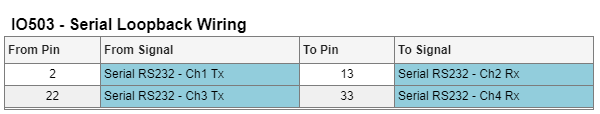

## Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO503_Loopback';
open_system(modelName);

### Model Description

In the model, a sine wave signal is encoded to an ASCII data stream and transmitted by channel 1 using the legacy mode. The legacy mode is used as it supports the same data type as the [ASCII Encode](https://mathworks.com/help/slrealtime/io_ref/asciiencode.html) block outputs, which is a NULL-terminated character string with a delimiter after the ASCII-encoded variable. Consequently, it is easy to extract the encoded variable and only complete messages are decoded.

Channel 3 uses a simple byte transferring mode, where the number of transferred bytes is defined by the count input in the Transmit channel block. Due to the fixed size of the hardware FIFO (64 bytes deep), byte padding is required.

On the receiving side, the ASCII data stream from channel 2 is buffered and then decoded to extract the original sine wave. Buffering is required as a partially complete message might be available when the [Serial - Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_serial_read) block is executed. To ensure compatibility with the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) blocks' input port data type, the receive track is configured to use the NULL-terminated character string which is sent from channel 1. The size of the software FIFO is set to double the size of the hardware FIFO to prevent data loss in case of an overflow. The [FIFO read](https://mathworks.com/help/slrealtime/io_ref/fiforead.html) block parses the data stream received for the specified delimiter ('\r' = 13) in order to be able to extract a complete message. The maximum read size is set to the same size as the software FIFO to ensure that all messages are read if multiple messages are available. The default value of one is used for the minimum read size: the delimiter will therefore ensure that only complete messages are output. No single bytes will be output**.** Once a complete message is available in the software FIFO, it can be decoded by the [ASCII Decode](https://mathworks.com/help/slrealtime/io_ref/asciidecode.html) block.

Channel 4 outputs all the received bytes: the number of received bytes is indicated by the count output. The example is setup up with a large enough sample rate and a high baud rate to have enough time to transmit the data over the serial link before the next sample step is triggered. Note that the amount of bytes received might still vary from run-to-run as in this case no synchronization and buffering is used.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Possible Issues

A problem has been encountered with the FIFO Write block used in the legacy configuration with the ASCII workflow. The error PopUp "FIFO overflow: RX Ch2 overflow" may appear. 

The referenced FIFO is not linked to the Serial FIFO of the target or the module. In the ASCII workflow, the data is written to a dedicated FIFO and immediately read back so it can be formatted correctly for ASCII decoding. The FIFO Write writes to the FIFO, and the FIFO Read reads the FIFO when it detects the delimiter. 

If, for some reason, the messages are not sent correctly, the delimiter may not be transmitted In this case, the FIFO is filled but not emptied, eventually overflowing. One of the causes of the incorrect transmission is unreliable wiring of the terminal board. This ASCII workflow is not tolerant of wiring issues.

To resolve this issue there are three solutions:

- Check the wiring.

- Uncheck the "Read to delimiter" option in the FIFO Read block. (This option is usually suggested to have checked in the ASCII workflow.)

- Do not use the ASCII workflow with the FIFO blocks.

### Check the Results

To check the loopback is working as expected, open the first Simulink scope connected to the Receive channel 2 block and the second scope connected to the Receive channel 4 block.  In the first scope, a sine wave signal must be displayed and on the second scope, a counter signal and the amount of bytes received (represented by a straight yellow line):

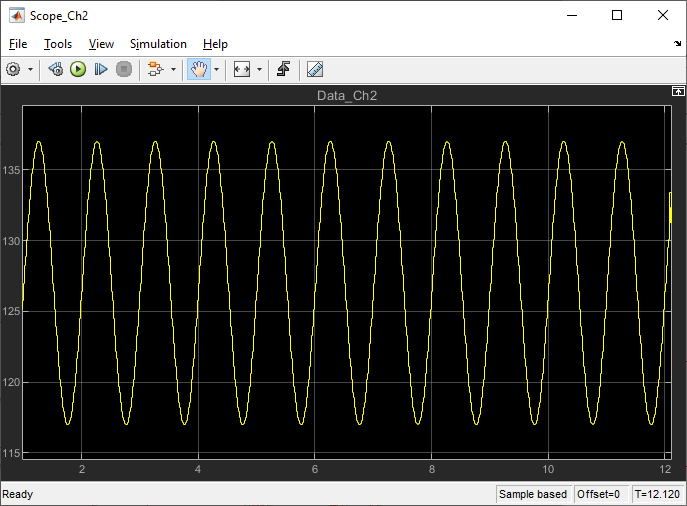 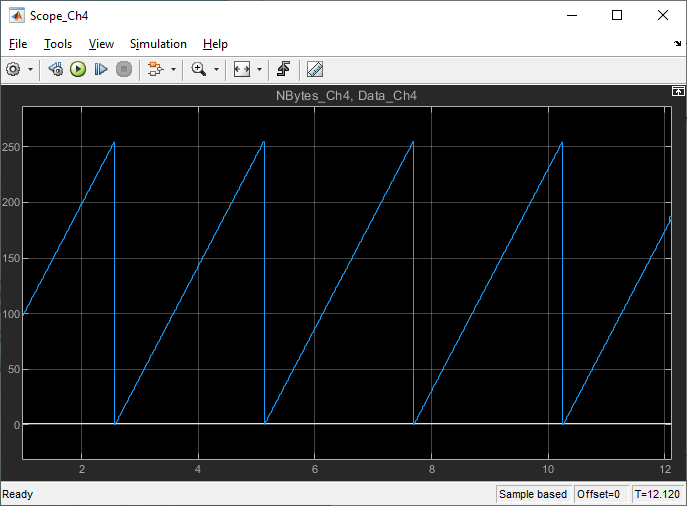

## Additional References

- [IO503 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io50Xio581)